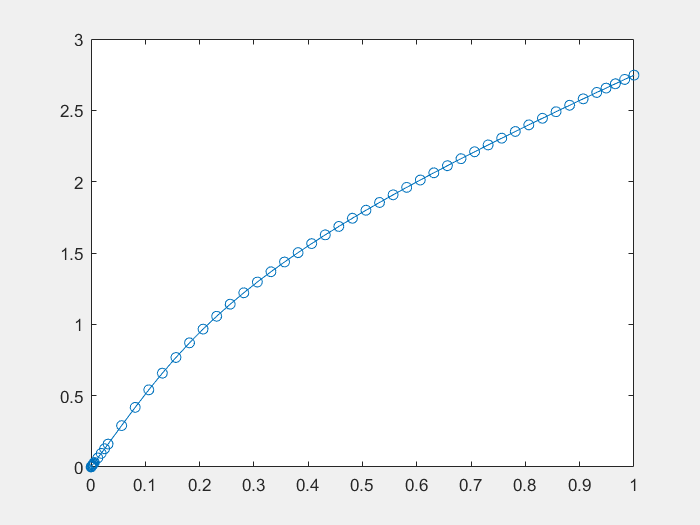

clear all
close all
opt=odeset('OutputFcn','odeplot');
f=@(t,y) y./(t+1)+5*(t+1)./(1+25*t.^2);
sol=@(t) (t+1).*(atan(5*t));
[t,u]=ode45(f,[0 1],0,opt);

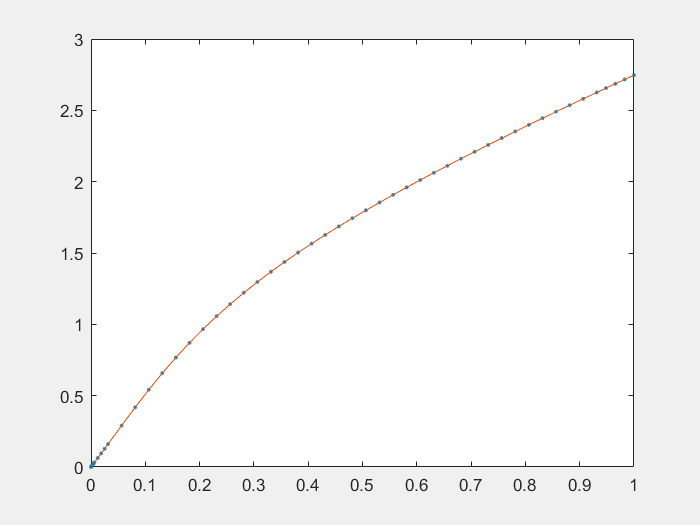

plot(t,u,'.-')
hold on 
fplot(sol,[0 1])

err=norm(u-sol(t),inf)

err = 1.2162e-05

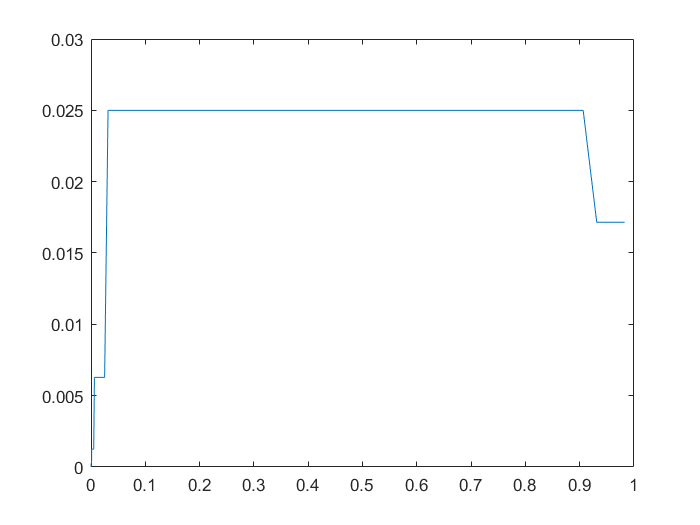

h=t(2:end)-t(1:end-1);
figure
plot(t(1:end-1),h)

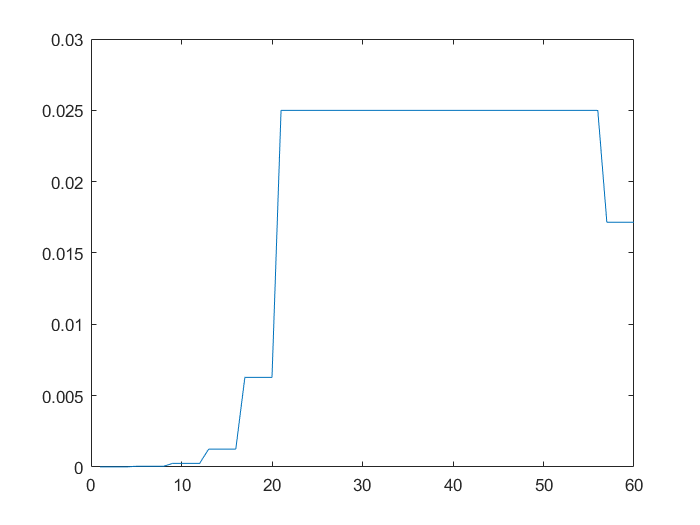

plot(h)

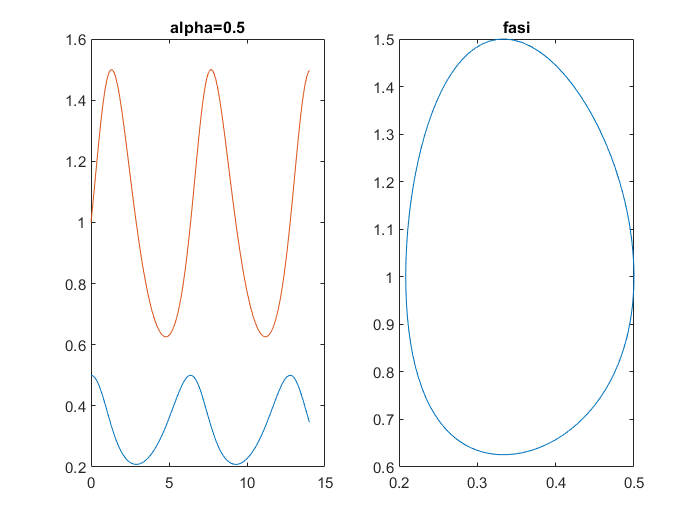

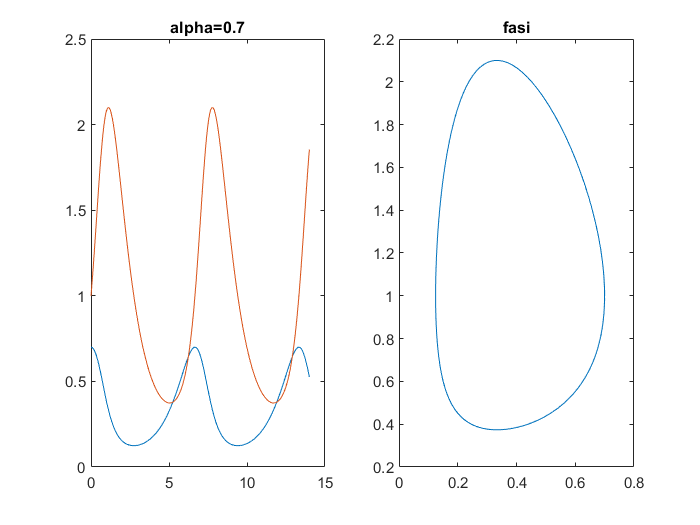

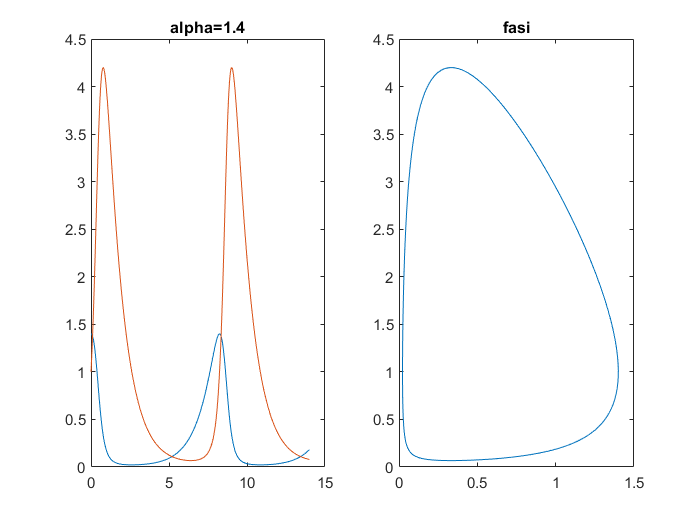

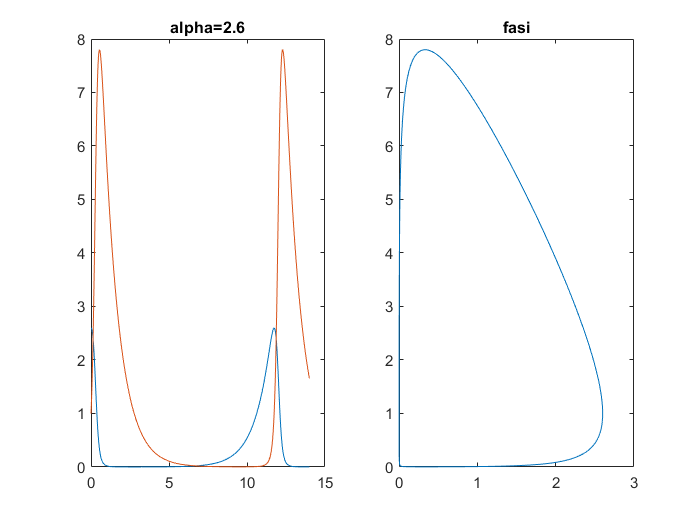

clear all
close all
opt=odeset("RelTol",1e-6);
a=1;b=1;c=2;d=3;beta=1;
for alpha=[0.5,0.7,1.4,2.6]
    f=@(t,y) [(a-b*y(2)).*y(1);(-close+d*y(1)).*y(2)];
    y=[alpha beta];
    [t,u]=ode45(f,[0 14],y,opt);
    figure
    subplot(1,2,1)
    plot(t,u)
    title("alpha="+alpha)
    subplot(1,2,2)
    plot(u(:,1),u(:,2))
    title("fasi")
    pause
end

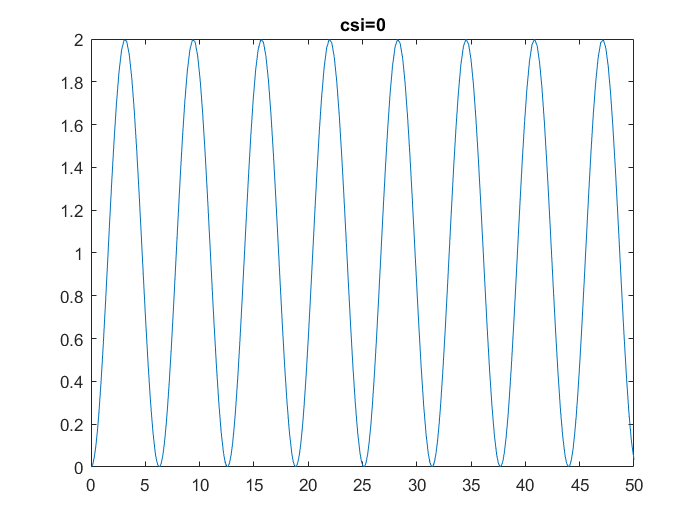

ma = 1.9993

tm = 196

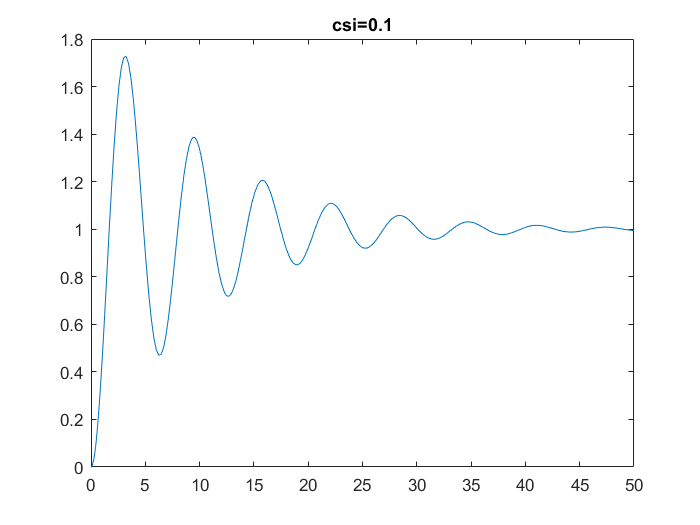

ma = 1.7269

tm = 38

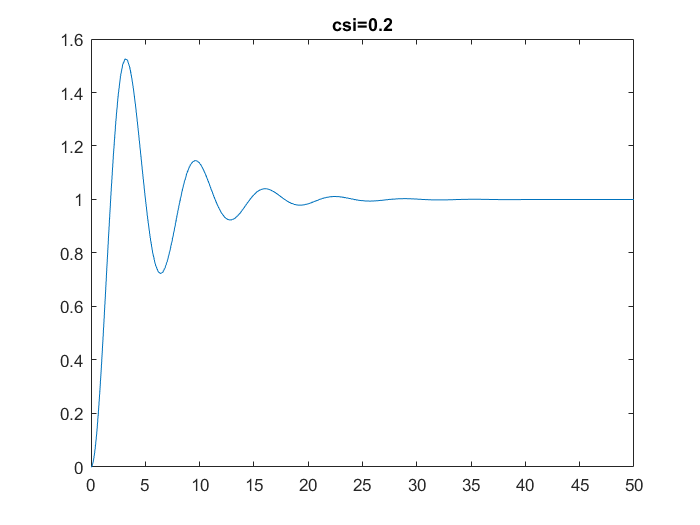

ma = 1.5254

tm = 39

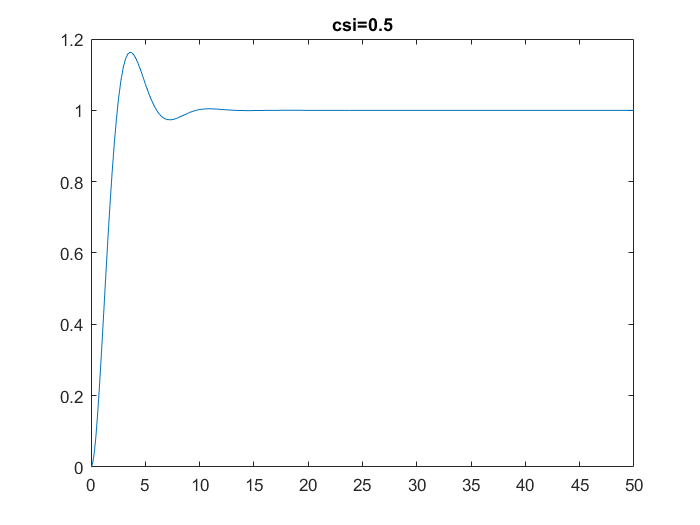

ma = 1.1628

tm = 42

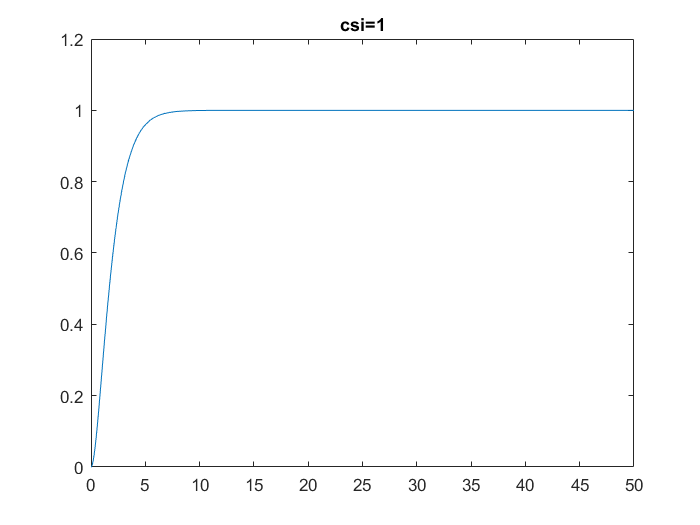

ma = 1.0000

tm = 129

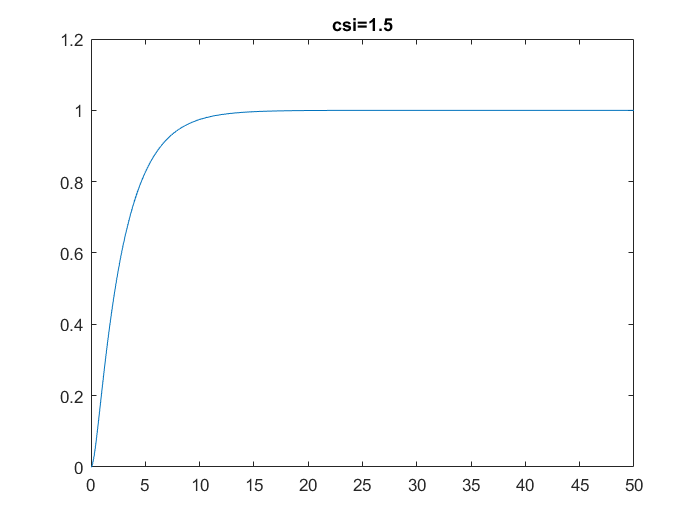

ma = 1.0000

tm = 201

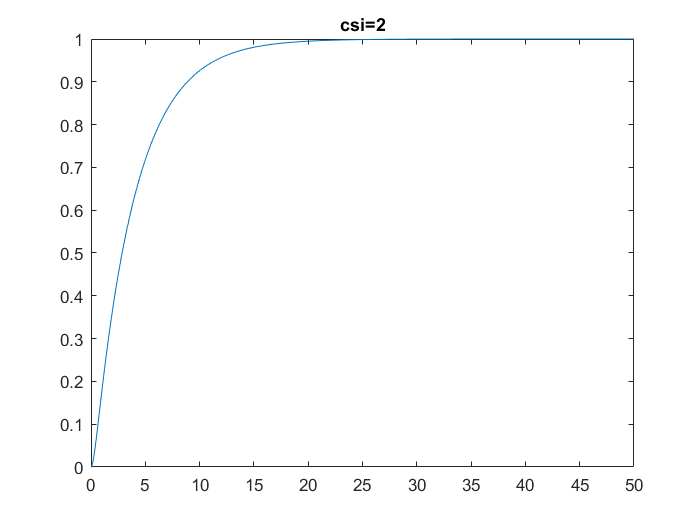

ma = 1.0000

tm = 269

clear all
close all
omega=1;alpha=0;beta=0;
int=[0 50];
y=[alpha beta];
Vf=[];Ovs=[];Tm=[];CSI=[0,0.1,0.2,0.5,1,1.5,2];
for csi=CSI
    F=@(t,y) [y(2);1-2*csi*omega*y(2)-omega^2*y(1)];
    [t,u]=ode45(F,int,y);
    figure
    plot(t,u(:,1))
    title("csi="+csi)
    Vf=[Vf u(end,1)];
    [ma,tm]=max(u(:,1))
    if tm==length(u(:,1))
        ovs=nan;
        Tm=[Tm nan];
    else
        ovs=ma-Vf(end);
        Tm=[Tm t(tm)];
    end
    Ovs=[Ovs ovs];
    
end

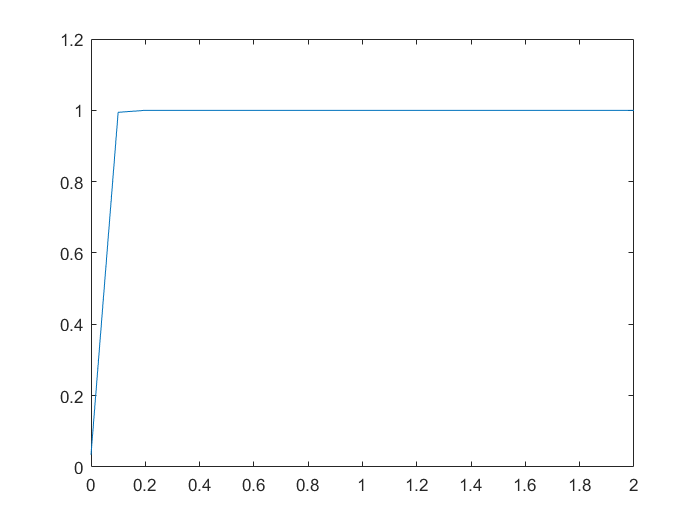

plot(CSI,Vf)

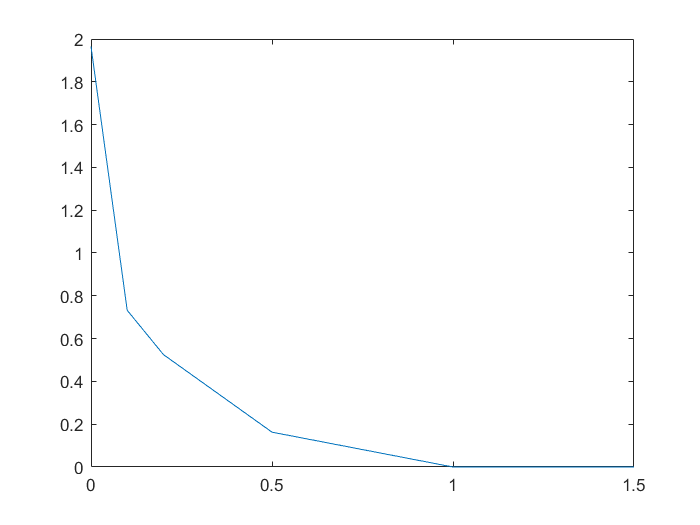

plot(CSI,Ovs)

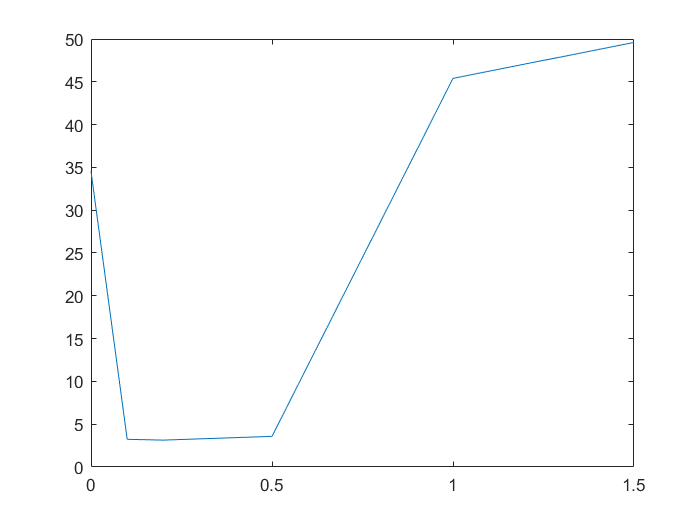

plot(CSI,Tm)

clear all
close all
int=[0 100];
for mu=[0.1 1 10 100]
    F=@(t,y) [y(2);mu*(1-y(1).^2).*y(2)-y(1)];
    
end


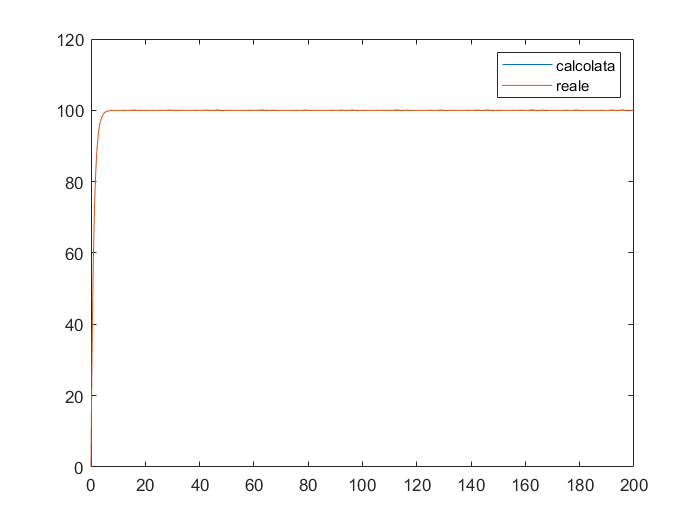

clear all
close all
int=[0 200];y0=0;
f1=@(t,y) 100-y;
f=@(t) 100*(1-exp(-t));
[t,u]=ode45(f1,int,y0);
plot(t,u)
hold on
fplot(f,int)
legend("calcolata","reale")

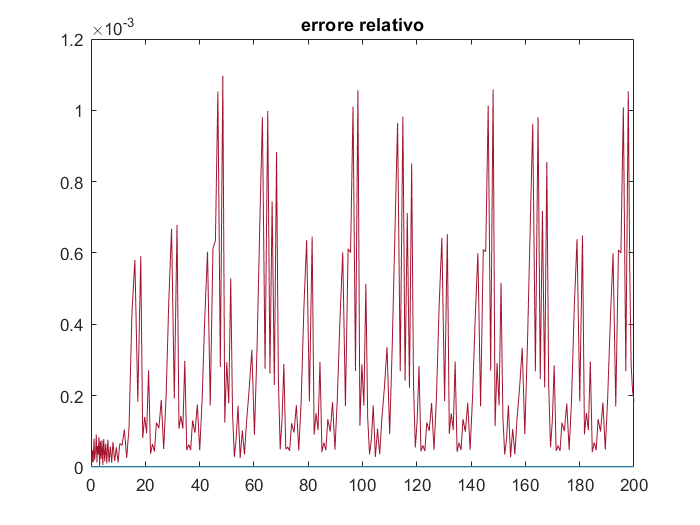

figure
E=abs((u-f(t))/f(t));
plot(t,E)
title("errore relativo")

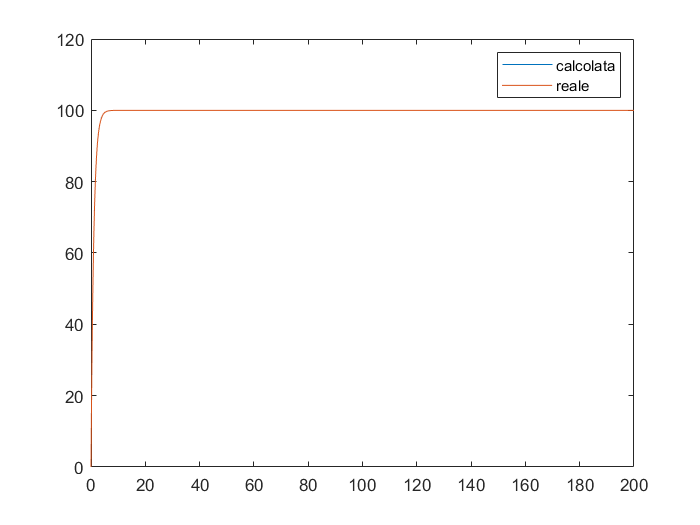

opt=odeset('RelTol',1e-6);
[t,u]=ode45(f1,int,y0,opt);
plot(t,u)
hold on
fplot(f,int)
legend("calcolata","reale")

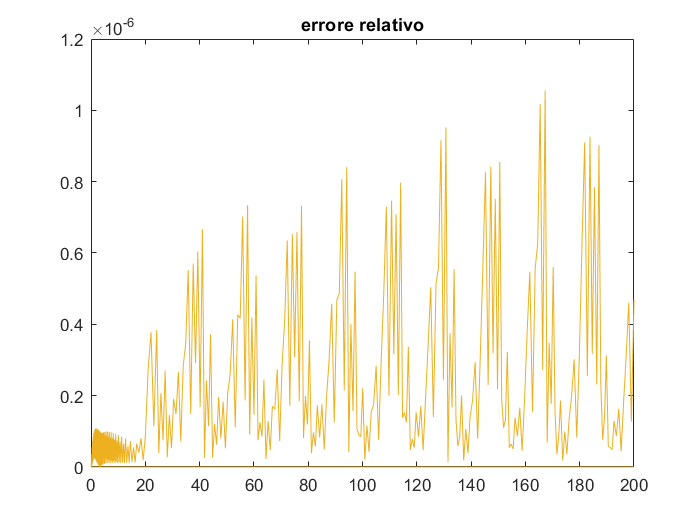

figure
E=abs((u-f(t))/f(t));
plot(t,E)
title("errore relativo")